備註：

- 此文件建議用.mlx檔閱讀，因為PDF會截掉右邊一點點

- 要執行的軟體在執行檔資料夾裡，自拍照比較小的那個，執行檔不用下載matlab也可以使用

- 執行檔go太多次可能會當機，要使用工作管理員關掉

- 程式碼資料夾有沒編譯過的檔案

## 雙擺(Double Pendulum)

### 前言

  這是一個模擬雙擺程式，程式大致展示擺桿的模擬、兩個角度對時間的圖形函數以及兩個角度對彼此的圖形函數。

### 設定

  基本設定與假設：

- 擺桿沒有質量只有長度

- 兩個擺桿末端各有一個有質量的球

- 只考慮重力與繩張力

  如下圖所示

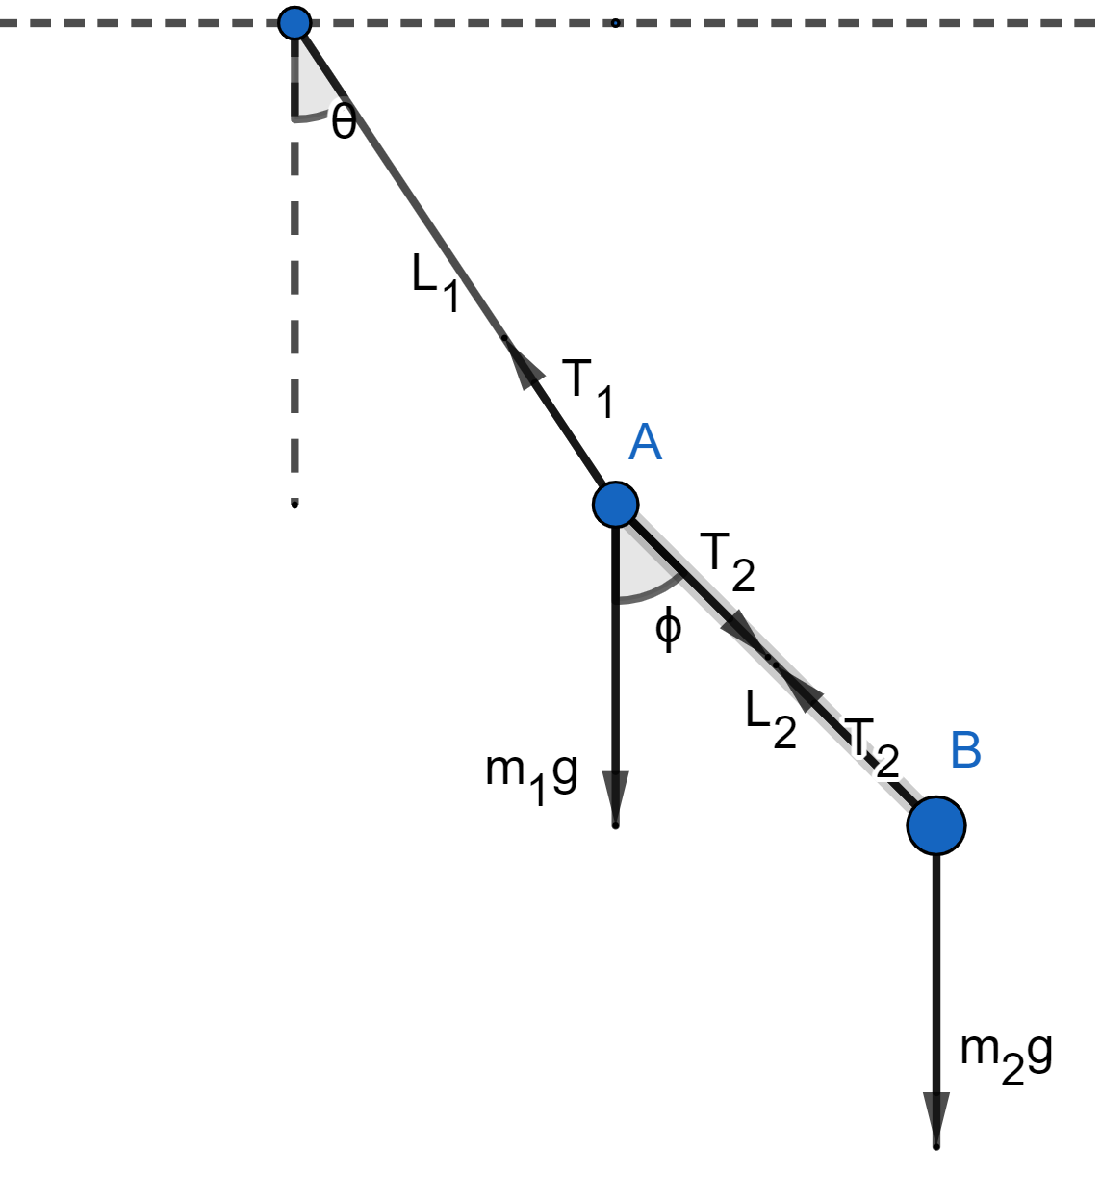

接下來會用Symbolic Tools 來計算微分方程組。

首先設定要用的變數、位置函數、速度函數與加速度函數

syms theta(t) phi(t) L_1 L_2 m_1 m_2 g
% position of A
x_1 = L_1*sin(theta);
y_1 = -L_1*cos(theta);
% position of B
x_2 = x_1 + L_2*sin(phi);
y_2 = y_1 - L_2*cos(phi);
% velocity
vx_1 = diff(x_1);
vy_1 = diff(y_1);
vx_2 = diff(x_2);
vy_2 = diff(y_2);
% accerleration
ax_1 = diff(vx_1);
ay_1 = diff(vy_1);
ax_2 = diff(vx_2);
ay_2 = diff(vy_2);

### 力學分析

第一步要解T_1與T_2，意思是要用上面設的變數(theta phi m_1 m_2 L_1 L_2 g)來表達T_1 T_2，所以先設T_1 T_2為變數

syms T_1 T_2

因為只有兩個點有質量，所以需要分析兩個點

- A：

% X direction
eqx_1 = m_1*ax_1(t) == -T_1*sin(theta(t)) + T_2*sin(phi(t));
% Y direction
eqy_1 = m_1*ay_1(t) == T_1*cos(theta(t)) - T_2*cos(phi(t)) - m_1*g;

- B：

% X direction
eqx_2 = m_2*ax_2(t) == -T_2*sin(phi(t));
% Y direction
eqy_2 = m_2*ay_2(t) == T_2*cos(phi(t)) - m_2*g;

% 用A點解
Tension = solve([eqx_1 eqy_1],[T_1 T_2]);
% 帶進B點
eq1 =subs(eqx_2,[T_1 T_2],[Tension.T_1 Tension.T_2]);
eq2 =subs(eqy_2,[T_1 T_2],[Tension.T_1 Tension.T_2]);

因為diff(theta,2)  與  diff(phi,2) 不是Symbolic variables ，所以要先把他們兩個替換掉

% diff(theta, 2) => DDtheta, diff(phi, 2) => DDphi
syms DDtheta DDphi
eq1 = subs(eq1,[diff(theta, 2) diff(phi, 2)],[DDtheta DDphi]);
eq2 = subs(eq2,[diff(theta, 2) diff(phi, 2)],[DDtheta DDphi]);

跟上面的  Tension  一樣，這裡要解 DDtheta 與 DDphi 的聯立方程式，然後順便化簡

Dtwo = solve([eq1 eq2],[DDtheta DDphi]);
diff_theta_2 = Dtwo.DDtheta;
% Compute simplified symbolic expression
diff_theta_2 = simplify(diff_theta_2,"Steps",6400);
diff_phi_2 = Dtwo.DDphi;
% Compute simplified symbolic expression
diff_phi_2 = simplify(diff_phi_2,"Steps",6400);
diff_theta_2

$$diff\_theta\_2 = \begin{array}{l} \frac{g\,m_{2}\,\sin\left(2\,\varphi \left(t\right)-\theta \left(t\right)\right)-\sin\left(\theta \left(t\right)\right)\,\left(2\,g\,m_{1}+g\,m_{2}\right)+2\,L_{2}\,m_{2}\,\sigma_{1}\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}+L_{1}\,m_{2}\,\sin\left(2\,\varphi \left(t\right)-2\,\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{L_{1}\,\left(2\,m_{1}+m_{2}+m_{2}\,\left(2\,{\sigma_{1}}^{2}-1\right)\right)}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\varphi \left(t\right)-\theta \left(t\right)\right) \end{array}$$

diff_phi_2

$$diff\_phi\_2 = \begin{array}{l} -\frac{\sigma_{2}\,\left(2\,L_{1}\,m_{1}\,\sigma_{3}+2\,L_{1}\,m_{2}\,\sigma_{3}\right)+\sin\left(\varphi \left(t\right)\right)\,\left(g\,m_{1}+g\,m_{2}\right)+g\,m_{1}\,\sigma_{1}+g\,m_{2}\,\sigma_{1}+L_{2}\,m_{2}\,\sin\left(2\,\varphi \left(t\right)-2\,\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}}{L_{2}\,\left(2\,m_{1}+m_{2}+m_{2}\,\left(2\,{\sigma_{2}}^{2}-1\right)\right)}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\varphi \left(t\right)-2\,\theta \left(t\right)\right)\\ \sigma_{2}=\sin\left(\varphi \left(t\right)-\theta \left(t\right)\right)\\ \sigma_{3}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2} \end{array}$$

因為要使用oed45來解微分方程，按照格式的寫法需要用 y 和dydt 來記錄 theta 與 phi，所以這裡再做一次替換

syms y(i)
diff_theta_2 = subs(diff_theta_2,[theta diff(theta) phi diff(phi)], [y(1) y(2) y(3) y(4)])

$$diff\_theta\_2 = \begin{array}{l} -\frac{\sin\left(y\left(1\right)\right)\,\left(2\,g\,m_{1}+g\,m_{2}\right)+g\,m_{2}\,\sin\left(y\left(1\right)-2\,y\left(3\right)\right)+2\,L_{2}\,m_{2}\,\sigma_{1}\,{y\left(4\right)}^{2}+L_{1}\,m_{2}\,{y\left(2\right)}^{2}\,\sin\left(2\,y\left(1\right)-2\,y\left(3\right)\right)}{L_{1}\,\left(2\,m_{1}+m_{2}+m_{2}\,\left(2\,{\sigma_{1}}^{2}-1\right)\right)}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(y\left(1\right)-y\left(3\right)\right) \end{array}$$

diff_phi_2 = subs(diff_phi_2,[theta diff(theta) phi diff(phi)], [y(1) y(2) y(3) y(4)])

$$diff\_phi\_2 = \begin{array}{l} \frac{\sigma_{2}\,\left(2\,L_{1}\,m_{1}\,{y\left(2\right)}^{2}+2\,L_{1}\,m_{2}\,{y\left(2\right)}^{2}\right)-\sin\left(y\left(3\right)\right)\,\left(g\,m_{1}+g\,m_{2}\right)+g\,m_{1}\,\sigma_{1}+g\,m_{2}\,\sigma_{1}+L_{2}\,m_{2}\,{y\left(4\right)}^{2}\,\sin\left(2\,y\left(1\right)-2\,y\left(3\right)\right)}{L_{2}\,\left(2\,m_{1}+m_{2}+m_{2}\,\left(2\,{\sigma_{2}}^{2}-1\right)\right)}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,y\left(1\right)-y\left(3\right)\right)\\ \sigma_{2}=\sin\left(y\left(1\right)-y\left(3\right)\right) \end{array}$$

複製上面的結果就可以整理出下面的方程組，就能使用ode45解方程組，得到  theta  與  phi  對時間的函數了

%dydt(1) = y(2);
%dydt(2) = -(sin(y(1))*(2*g*m_1 + g*m_2) + g*m_2*sin(y(1) - 2*y(3)) + ...
%            2*L_2*m_2*sin(y(1) - y(3))*y(4)^2 + L_1*m_2*y(2)^2*sin(2*y(1) - 2*y(3)))/...
%          (L_1*(2*m_1 + m_2 + m_2*(2*sin(y(1) - y(3))^2 - 1)));
%dydt(3) = y(4);
%dydt(4) = (sin(y(1) - y(3))*(2*L_1*m_1*y(2)^2 + 2*L_1*m_2*y(2)^2) -...
%           sin(y(3))*(g*m_1 + g*m_2) + g*m_1*sin(2*y(1) - y(3)) + g*m_2*sin(2*y(1) - y(3)) +...
%           L_2*m_2*y(4)^2*sin(2*y(1) - 2*y(3)))/...
%           (L_2*(2*m_1 + m_2 + m_2*(2*sin(y(1) - y(3))^2 - 1)));

### GUI 圖形使用者介面

接下來 我想做模擬擺動和圖形分析。

軟體介面會顯示四個圖，分別是模擬圖、theta對phi的圖、theta(t)與phi(t)的比較圖、B點的軌跡圖

左上方有參數的調整，分別為m1 m2 L1 L2 g theta0/pi phi0/pi

注意theta0/pi phi0/pi代表的是初始角度除以pi

左下方的按鈕分別為：go     let m2=m1     let L2=L1     plot motion     clear motion

按下  go  會開始跑 模擬圖、theta對phi的圖、theta(t)與phi(t)的比較圖  三張圖，如下：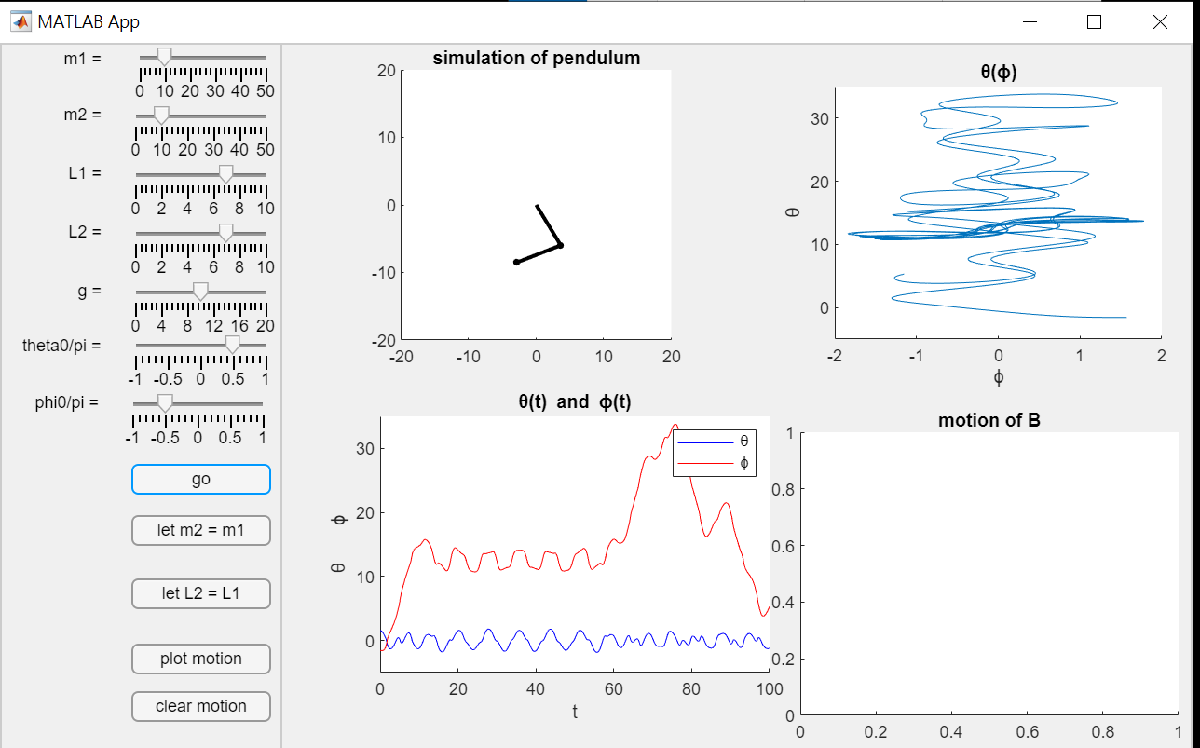

注意  let m2=m1     let L2=L1  兩個按鈕的邏輯與寫程式碼是一樣的，以  m1  L1  為主，讓  m2  L2  分別與之相等

最後兩個按鈕只對第四張圖(軌跡圖)作用，按下  plot motion  繪畫出當前參數的B點軌跡，按下  clear motion  則清除圖上所有軌跡

注意按下  plot motion 不會清除之前畫的軌跡圖，這是為了比較不同參數的軌跡變化，如圖：

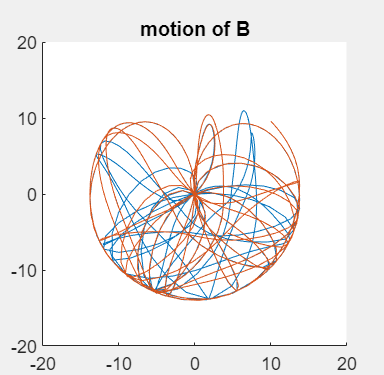

### 模擬圖分析

最後，我想特別貼幾張圖，然後分析觀察到的現象

- theta  與  phi  都很小時，擺動大致成週期運動

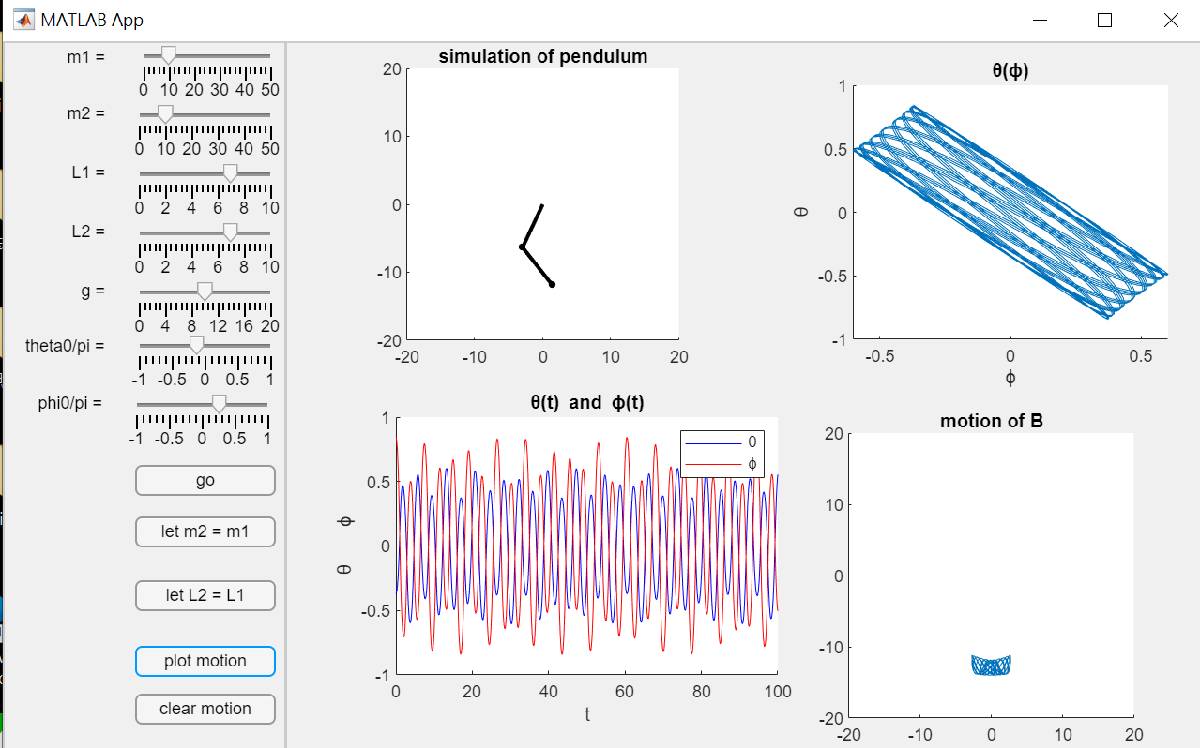

- theta  與  phi  都很大時，擺動是混亂的，而且雖然角度都一樣，不一樣的參數  g  會導致截然不同的軌跡

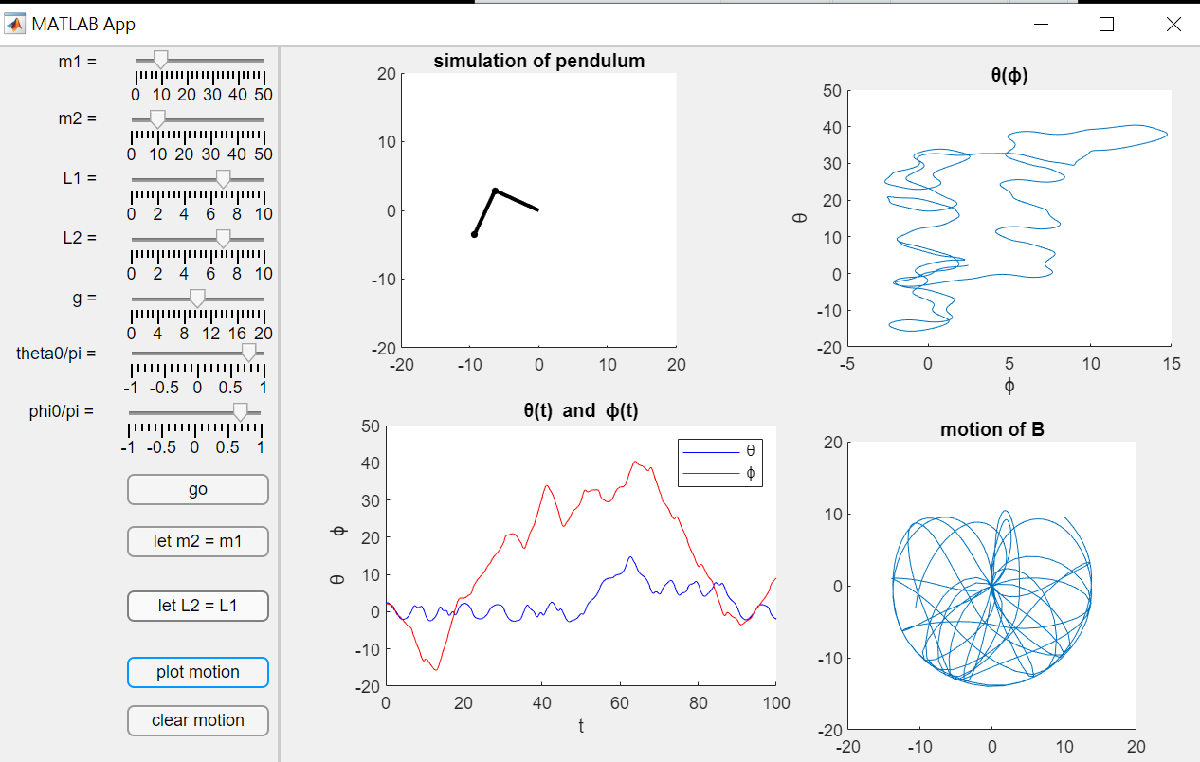

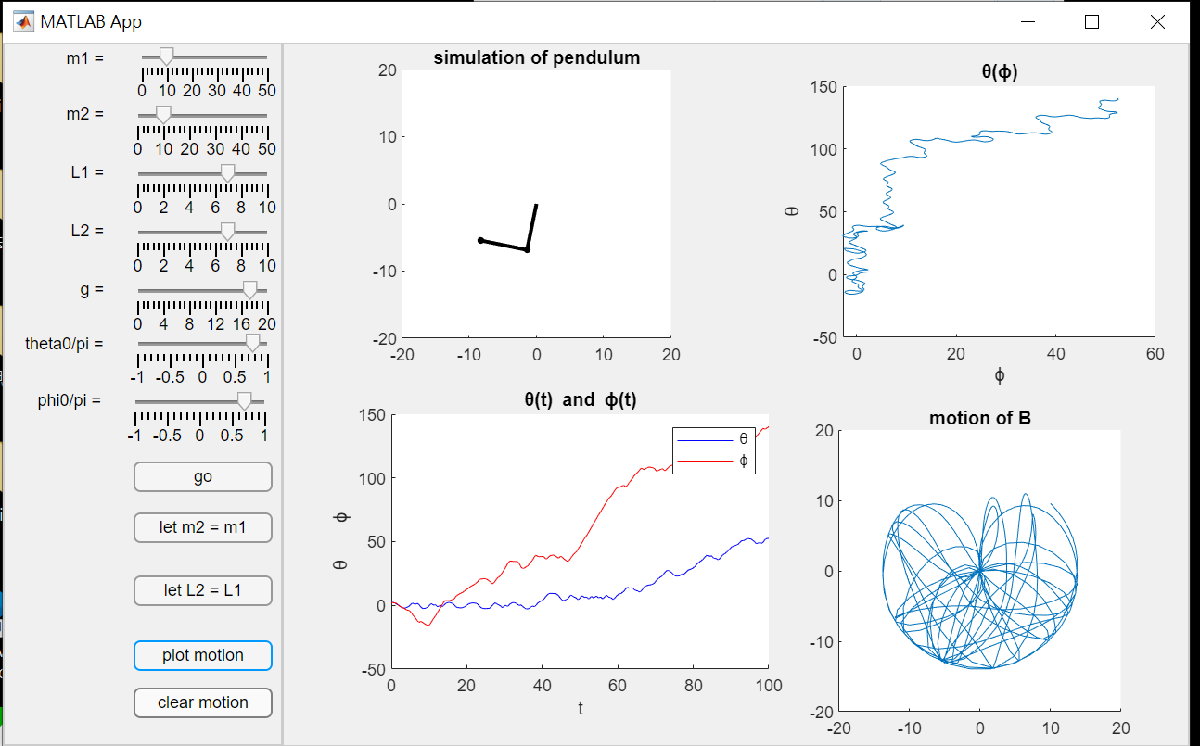

由左下與右上圖可以知道：不同的g會導致不一樣的軌跡

- theta 與 phi 都等於一時，雙擺垂直地面向上，雖然一開始不動，但過幾秒後竟然開始運動，可能是電腦的演算誤差導致

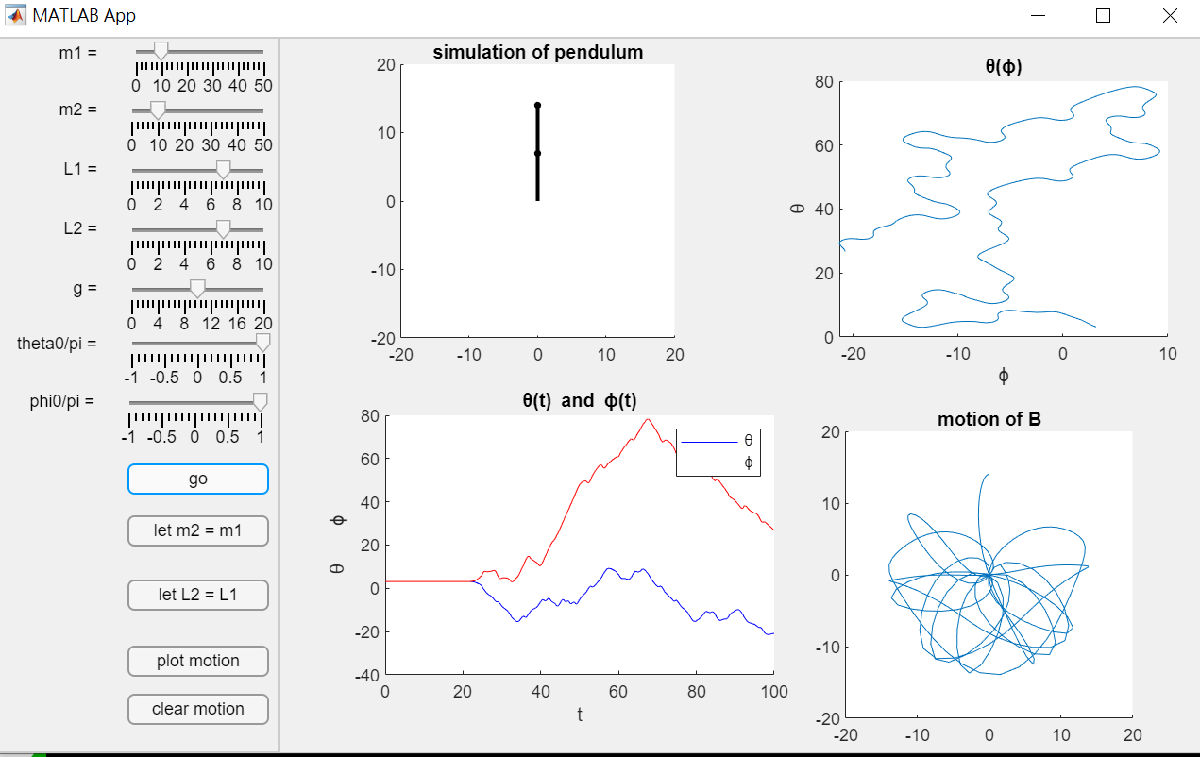

### 結論與問題

- 此程式的寫法會造成記憶體爆滿，在經過多次模擬後，程式會當機，需要開啟工作管理員關閉程式

- 此程式的目的在於了解渾沌理論，可以在思考如何在一張圖上同時模擬不同參數的雙擺

- 可以思考軌跡圖也與模擬圖一樣做成動畫，然後與模擬圖疊再一起，更容易看出軌跡混亂的特性